# Enhancement of Images

In this script, we try to understand how an image can be enhanced (improved) so that it become easier for us to extract the necessary features from it. In doing so, we will follow the following four steps -

- Converting the image to a *grayscale*.

- Cropping the image

- Understanding variation of pixel intensities in the image

- Improving the contrast of the image

% Reading an image
img=imread("../../data/data_sedimentation/sphere.png");  % image of a sphere

## Part 1: Converion to grayscale

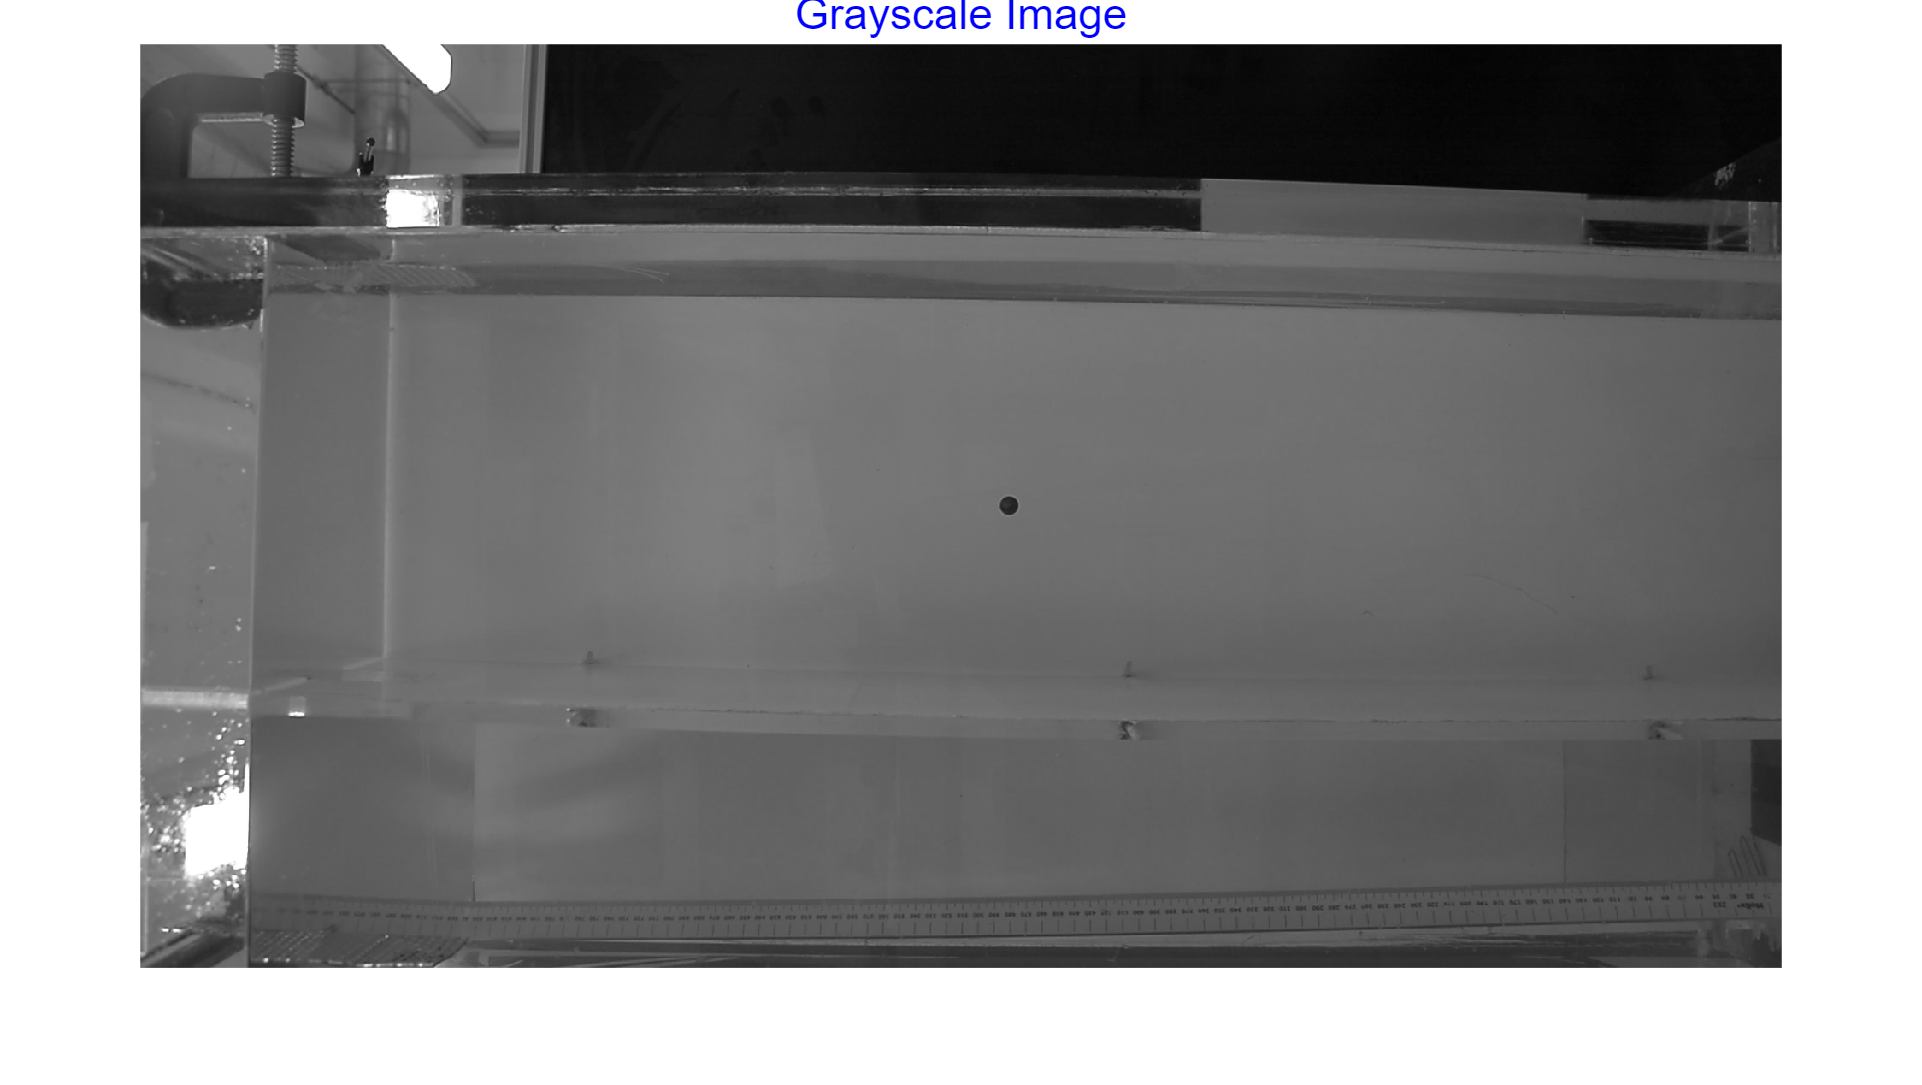

img_gray=im2gray(img);
image_viewer(img_gray,"Grayscale Image")

## Part 2: Cropping an Image

Here, I will store the value of the crop rectangle for future purposes.

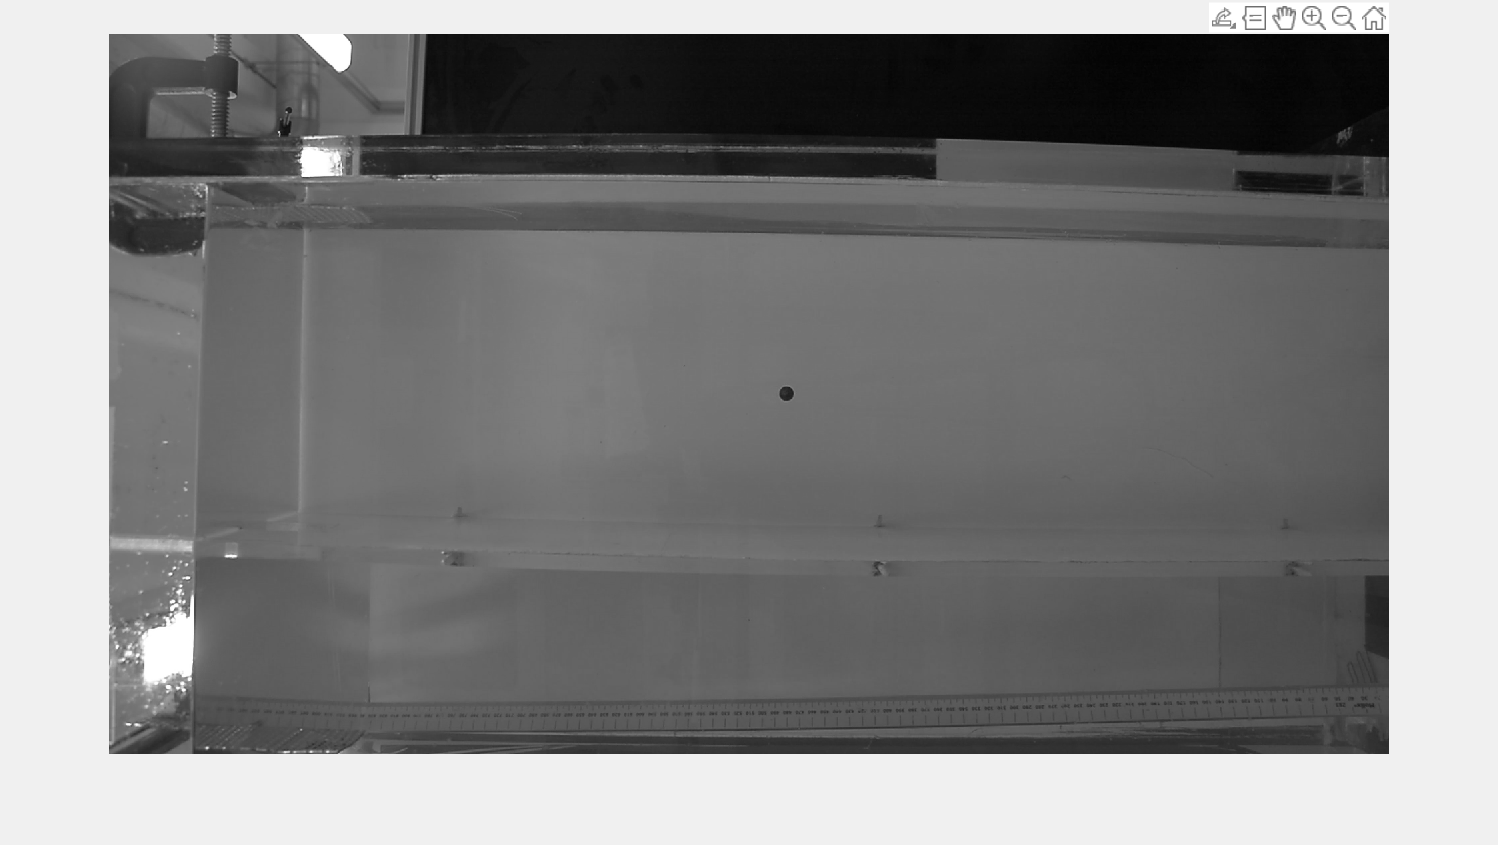

[img_crop,crop_rect]=imcrop(img_gray);

#### Visualising the crop windown over the full image

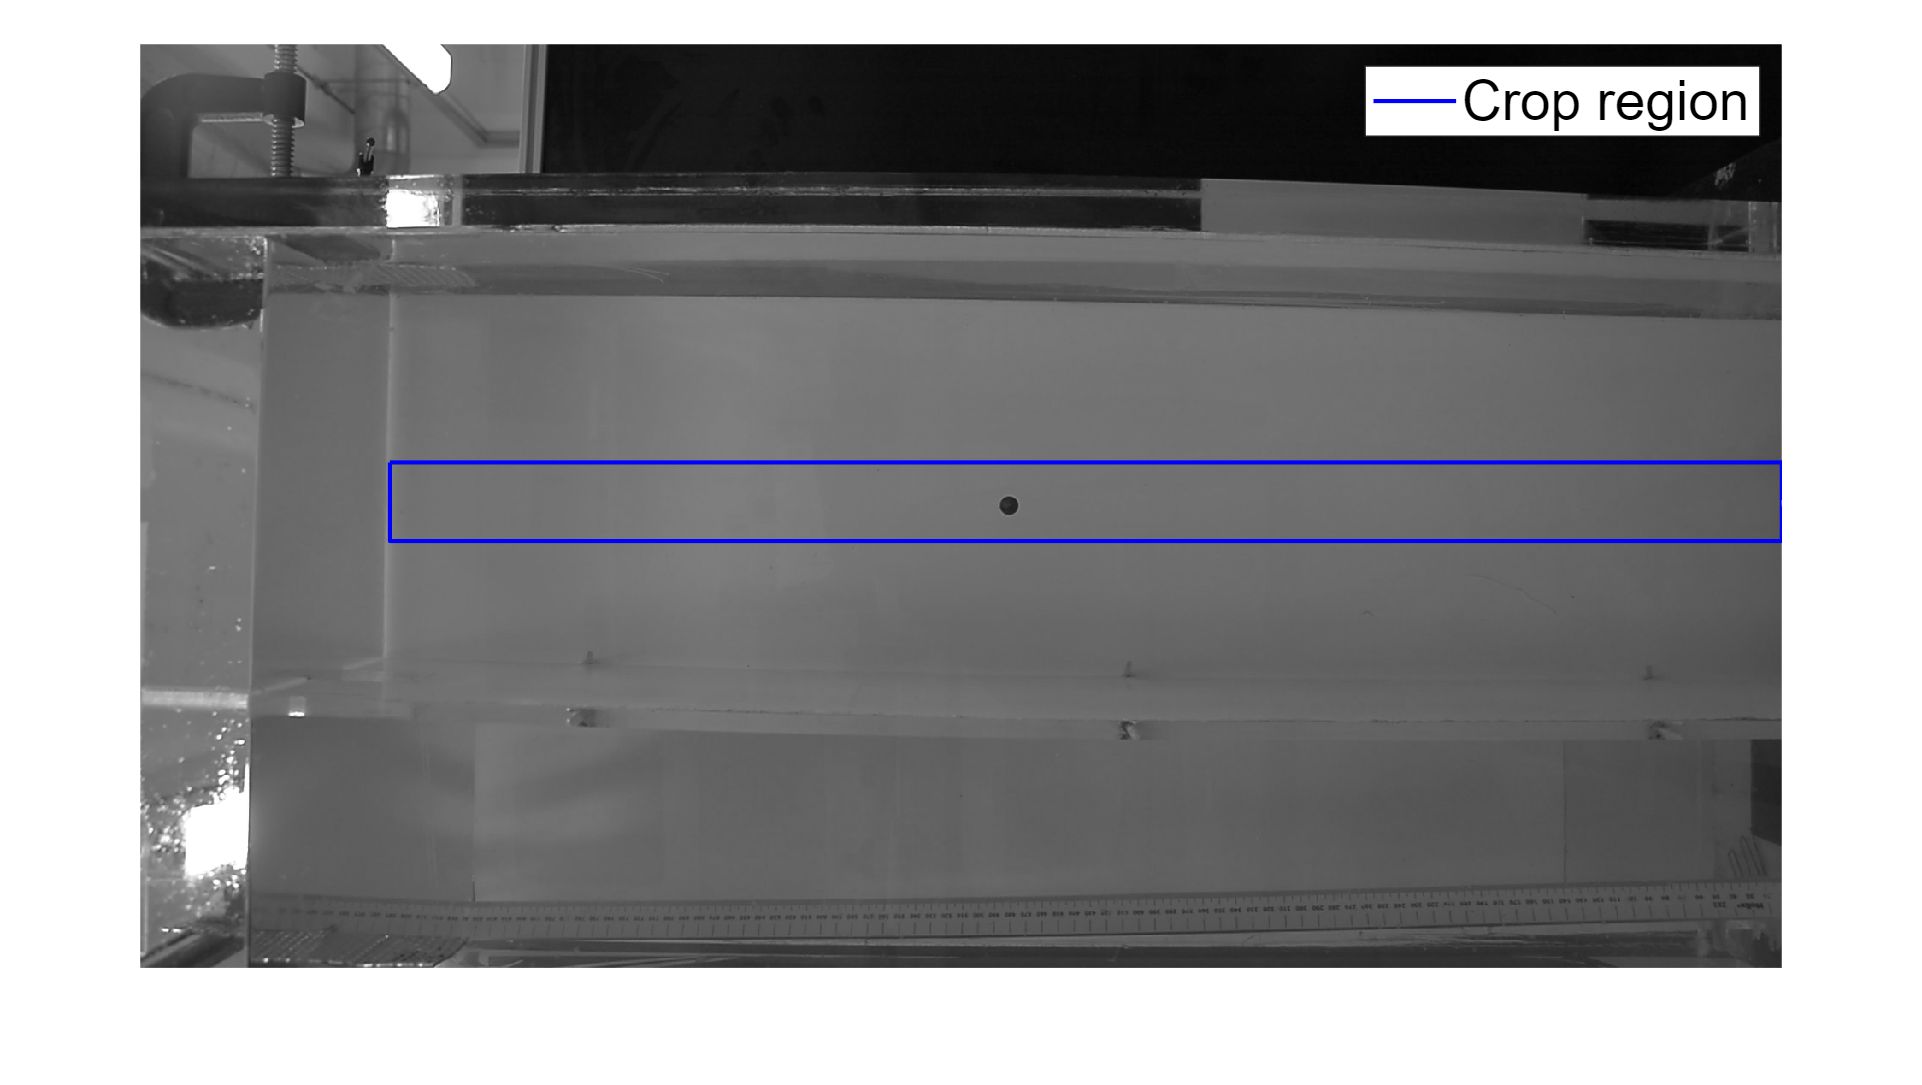

CropRectViewer(img_gray,crop_rect)

## Part 3: Understanding the pixel intensity variation

Now, we try to understand how the pixel intensities vary within the image. This will help us form some important decisions later.

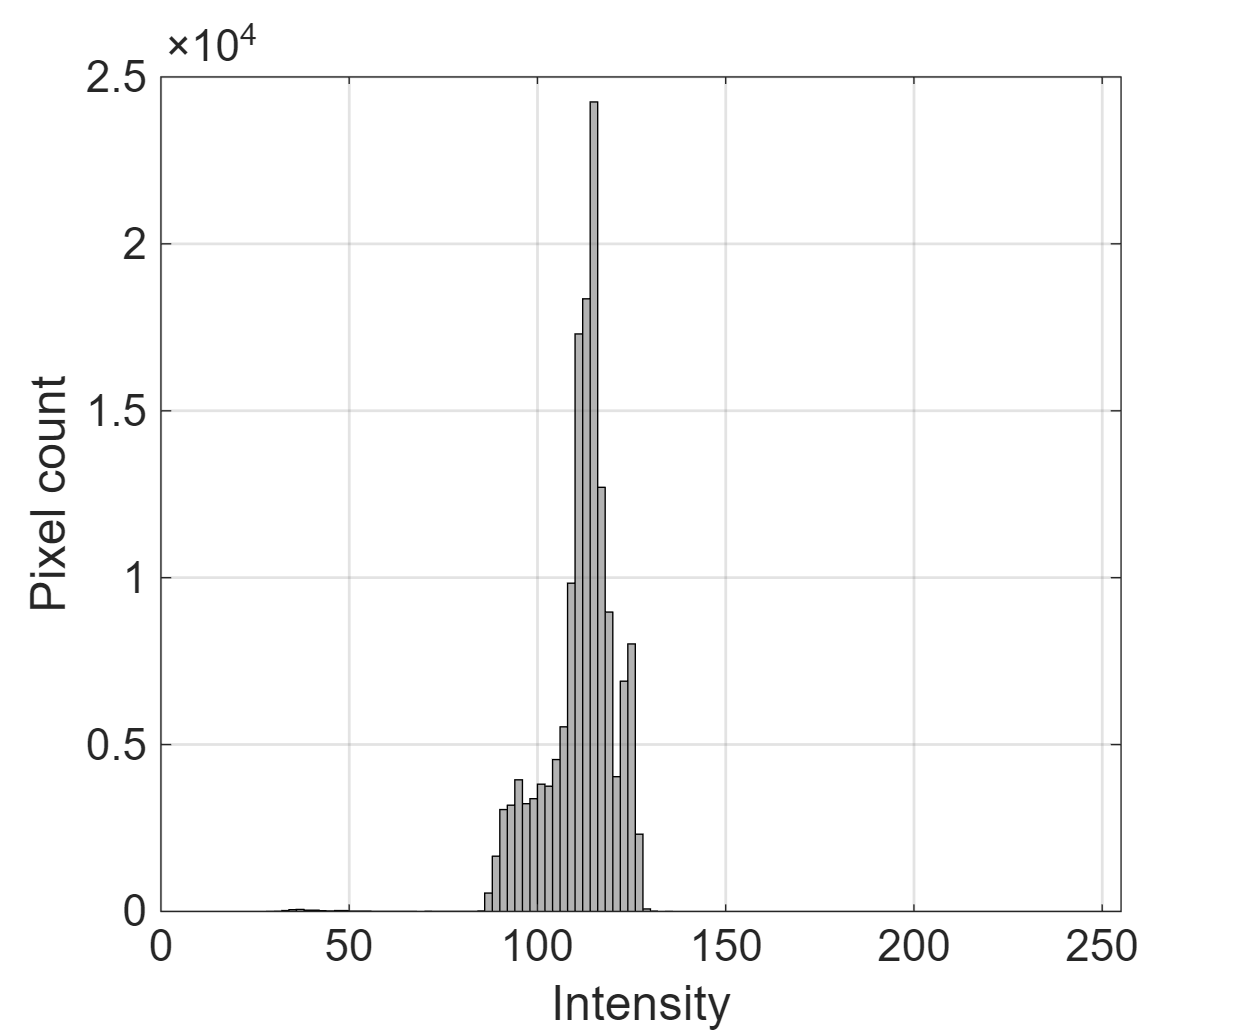

img_crop = imcrop(img_gray, crop_rect);
VisualiseHistogram(img_crop,2);

## Part 4: Enhancing the Image

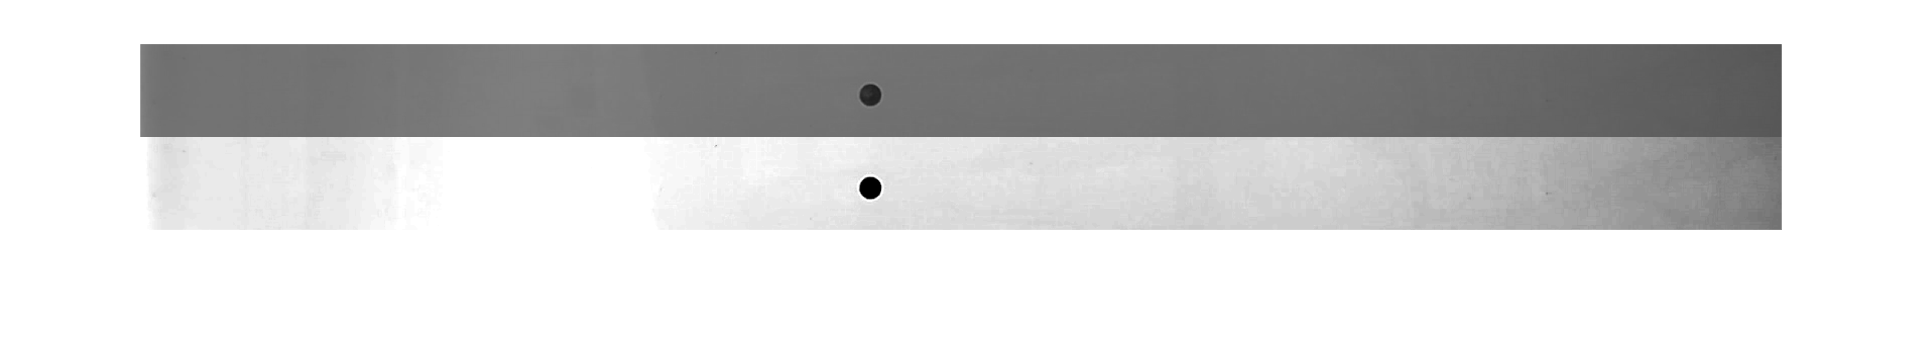

img_adj=imadjust(img_crop,[60/255,120/255],[0/255,255/255]);

figure;
montage({img_crop,img_adj})

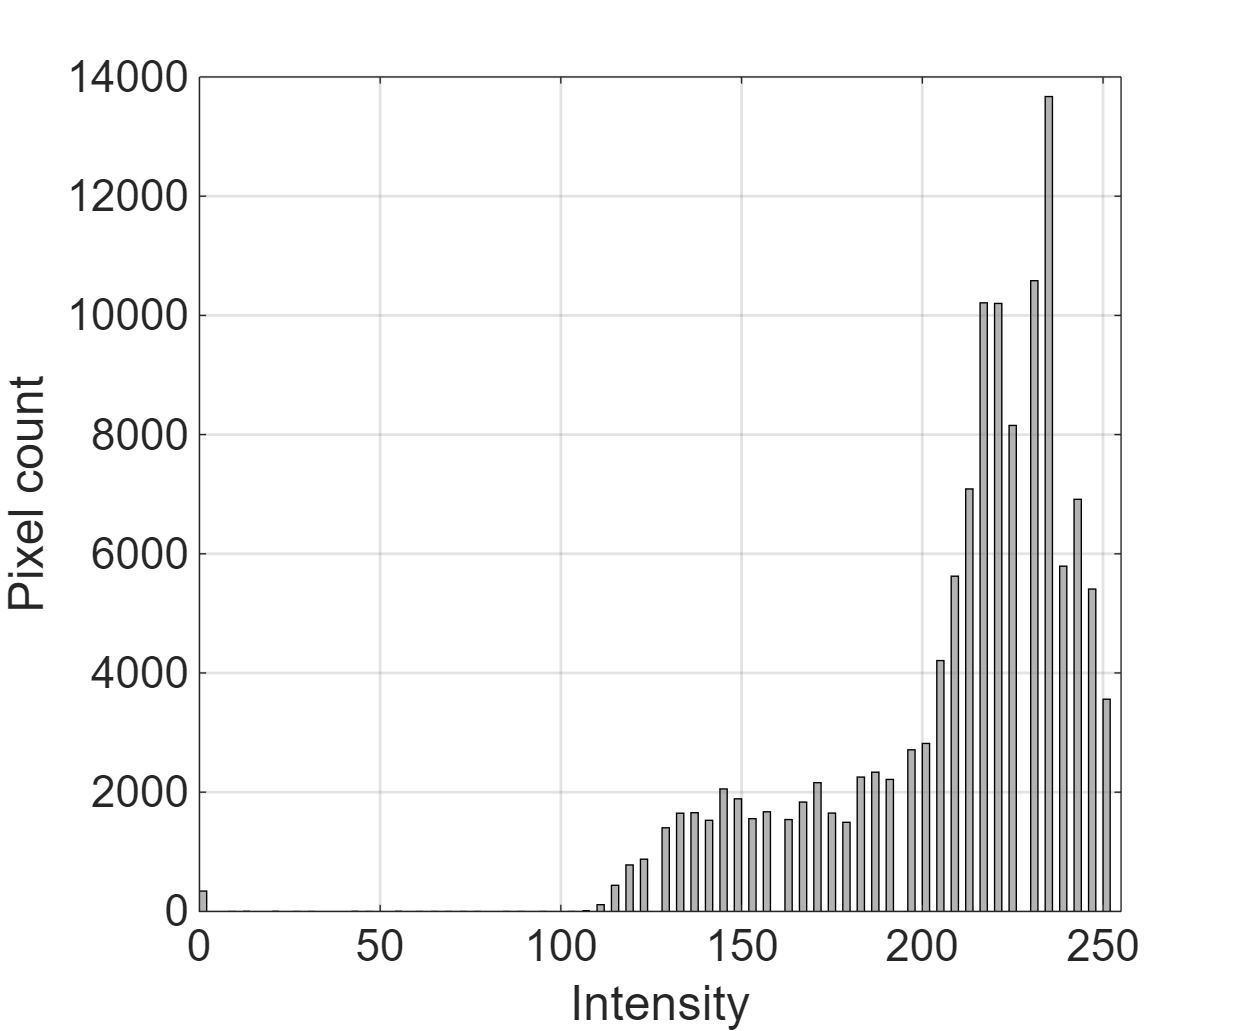

VisualiseHistogram(img_adj,2);